% GENERATE BODE PLOT OF SYSTEM BANDWIDTH

% Author: James Hope, Biosensing and Biorobotics Lab, 
% Department of Mechanical Engineering, University of Minnesota
% Contact: suhasabk@umn.edu

% Using kinematics function from Yuliya Smirnova, Copyright (c) 2019
% modified for compatibility with other functions 

% Using dynamics equations from Zhang et al 2012 doi:10.1017/S0263574711000622

Clear all 

    % constants
    Lp = 0.34; 
    Ld = 0.656;
    Rf = 0.19;
    Rm = 0.1;
    
    tincr = 0.01;
    
% anglular offsets of delta motors from reference frame x-axis
kappa_1 = 6*pi/4;    % (rad)
kappa_2 = pi/6;     % (rad)
kappa_3 = 5*pi/6;   % (rad)
% anglular offsets of delta motors from reference frame x-axis
kappa = [kappa_1, kappa_2, kappa_3];

% position    
X = 0;
Y = 0;
Z = -0.6;
r_forw = [X;Y;Z];

%velocity
Xdot = 0;
Ydot = 0;
Zdot = 0;
r_dot = [Xdot;Ydot;Zdot];

% acceleration
r_dotdot = [0;0;01];


% joint position
[theta1, theta2, theta3, fl] = IKinemDelta2(X, Y, Z, Rm, Rf, Ld, Lp);
theta = [theta1;theta2;theta3];

% Zhang vectors
[e_1,e_2,e_3,u_1,u_2,u_3,w_1,w_2,w_3,v_1,v_2,v_3] = Zhangvectors(Rf,Rm,Ld,Lp,theta,r_forw,kappa);

% Jacobian
[Jq,Jx] = DeltaJacobian2(u_1,u_2,u_3,w_1,w_2,w_3,v_1,v_2,v_3,Lp);
Jinv = inv(Jq)*Jx

Jinv =     0.0000    2.0381   -2.4762
   -1.7650   -1.0190   -2.4762
    1.7650   -1.0190   -2.4762


J = inv(Jinv)

J =    -0.0000   -0.2833    0.2833
    0.3271   -0.1636   -0.1636
   -0.1346   -0.1346   -0.1346



% joint vel accel
theta_dot = Jinv*r_dot;

[fr_dot] = f_r_dotcalc(u_1,u_2,u_3,w_1,w_2,w_3,v_1,v_2,v_3,Lp,Ld,r_dot);

theta_dotdot = Jinv*r_dot + fr_dot;

    
f_D = [0,0,0]';
        
g = 9.8;     % (m/s^2) accel. from gravity
z_hat = -[0 0 1]';

% system properties
mu_1 = 1; % (kg/m) of proximal linkage
mu_2 = 0.5; % (kg/m) of distal linkage
m_A = mu_1*Lp; % (kg) mass of proximal linkage
r_A = Lp/2;  % assume centre of gravity is halfway along the linkage
m_B = 0.25;  % (kg) lump mass at B
m_C = 2;     % (kg) mass of moving platform

% the inertia of the components in each kinematic chain:
I_A1 = 0.17;         % (kg.m^2) gearbox
I_A2 = mu_1*Lp^3/3;    % (kg.m^2) intermediate section
I_A3 = m_B*Lp^2;       % (kg.m^2) lump mass at B
I_A4 = 4*mu_2*Ld*Lp^2/3; % (kg.m^2) equivalent mass of distal links
I_A = I_A1 + I_A2 + I_A3 + I_A4;

Eta = m_C/I_A;
G = Eta*J'+inv(J);
Tau_a = I_A*G*r_dotdot; % Inertial torque
Tau_v = I_A*fr_dot;        % centrifuge/Coriolis torque
Tau_Ag = m_A*r_A*g*[cos(theta(1)) cos(theta(2)) cos(theta(3))]'; % gravitational torque from Delta arms
Tau_g = J'*m_C*g*z_hat + Tau_Ag;  % gravitational torque
Tau_d = J'*f_D;            % force exetered on delta platform by goniometer

JSIM = I_A*G

JSIM =     0.0000    1.1893   -0.9194
   -1.0300   -0.5947   -0.9194
    1.0300   -0.5947   -0.9194


TSIM1 = Jinv'*JSIM*Jinv

TSIM1 =     0.0000    7.4103   -9.0031
   -6.4175   -3.7052   -9.0031
   12.0543   -6.9596  -16.9109


TSIM = Jinv'*JSIM

TSIM =     3.6359    0.0000   -0.0000
    0.0000    3.6359   -0.0000
   -0.0000   -0.0000    6.8295




syms F_ext S_f S_p Y_v Y_r C_fb_pos C_fb_vel H_zoh s v 


s = tf('s') 

s =
 
  s
 
Continuous-time transfer function.




% Fext = 1;

% Transfer function H_zoh: zero order hold
Ts_delay = 0.0001   % delay time (s)

Ts_delay = 1.0000e-04

H_zoh = (1-exp(-s*Ts_delay))/(s*Ts_delay);
% 
H_zoh = 1;

% Virtual admittance Y_v:
k_a = 1;    % phase lead acceleration gain, 1 = no gain
m_v = 0.1;  % (kg) virtual mass
b_v = 0;  % (Ns/m) virtual damping
k_v = 0;     % (N/m) virtual stiffnes 
Y_v = (k_a*s^2 + s)/(m_v*s^2 + b_v*s + k_v);
Y_v = [Y_v 0 0;...
       0 Y_v 0;...
       0 0 Y_v];

% Y_v_trans = tf([k_a 1 0],[m_v b_v k_v])

% Robot admittance Y_r
% m_r = TSIM   % real robot mass (kg)
% b_r = zeros.*TSIM    % real robot damping (Ns/m)
Y_r = [1/TSIM(1,1)/s 0 0; 0 1/TSIM(2,2)/s 0; 0 0 1/TSIM(3,3)/s] 

Y_r =
 
  From input 1 to output...
       0.275
   1:  -----
         s
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
       0.275
   2:  -----
         s
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
       0.1464
   3:  ------
         s
 
Continuous-time transfer function.



%Y_r = [1/(m_r(1,1)*s+b_r(1,1)) 1/(m_r(1,2)*s+b_r(1,2)) 1/(m_r(1,3)*s+b_r(1,3));...
%       1/(m_r(2,1)*s+b_r(2,1)) 1/(m_r(2,2)*s+b_r(2,2)) 1/(m_r(2,3)*s+b_r(2,3));...
%       1/(m_r(3,1)*s+b_r(3,1)) 1/(m_r(3,2)*s+b_r(3,2)) 1/(m_r(3,3)*s+b_r(3,3))]

% real robot admittance
% Y_r_trans = tf([1],[m_r b_r])

% Feedback position controller 
k_p_p = 2;    % prop gain (Ns/m)
k_i_p = 0;    % integ gain (N/m)
k_d_p = 0;    % deriv gain
tc_p = 0.02;    % time constant (seconds to 65 % rise time to step response)
C_fb_pos = k_p_p + k_p_p/s + k_d_p*s/(tc_p*s + 1);
C_fb_pos = [C_fb_pos    0           0;...
            0           C_fb_pos    0;...
            0           0           C_fb_pos];

% Feedback velocity controller
k_p_v = 50;    % prop gain (Ns/m)
k_i_v = 30;    % integ gain (N/m)
k_d_v = 0;    % deriv gain
tc_v = 0.001;    % time constant (seconds to 65 % rise time to step response)
C_fb_vel = k_p_v + k_p_v/s + k_d_v*s/(tc_v*s + 1);
C_fb_vel = [C_fb_vel    0           0;...
            0           C_fb_vel    0;...
            0           0           C_fb_vel];

% assume perfect current control loop
k_g = 1.5;   % (Nm/A) motor constant
C_fb_i = 1*k_g';
C_fb_i = [C_fb_i    0           0;...
            0           C_fb_i    0;...
            0           0           C_fb_i];


% Sensor dynamics
tc_f = 0;
S_f = 1/(tc_f*s + 1);    % perfect sensor, S_f = 1
tc_v = 0;
S_p = 1/(tc_v*s + 1);    % perfect sensor, S_v = 1
% admittance output scaling parameter
S_cal = 1;
S_cal = [S_cal   0   0;...
         0   S_cal   0;...
         0   0   S_cal];

%post-sensor impedance
m_ps = 0.01;    % (kg)
Z_ps = m_ps*s;    % 
J = [1 0 0; 0 1 0; 0 0 1]

J =      1     0     0
     0     1     0
     0     0     1



A = Y_r*(inv(J')*C_fb_vel)

A =
 
  From input 1 to output...
       13.75 s + 13.75
   1:  ---------------
             s^2
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
       13.75 s + 13.75
   2:  ---------------
             s^2
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
       7.321 s + 7.321
   3:  ---------------
             s^2
 
Continuous-time transfer function.



B = Y_r*(inv(J')*(C_fb_vel*(inv(J)*C_fb_pos))) %*H_zoh

B =
 
  From input 1 to output...
       27.5 s^2 + 55.01 s + 27.5
   1:  -------------------------
                  s^3
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
       27.5 s^2 + 55.01 s + 27.5
   2:  -------------------------
                  s^3
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
       14.64 s^2 + 29.28 s + 14.64
   3:  ---------------------------
                   s^3
 
Continuous-time transfer function.



C = S_cal/s*Y_v

C =
 
  From input 1 to output...
       s^2 + s
   1:  -------
       0.1 s^3
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
       s^2 + s
   2:  -------
       0.1 s^3
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
       s^2 + s
   3:  -------
       0.1 s^3
 
Continuous-time transfer function.



D = S_p/s

D =
 
  1
  -
  s
 
Continuous-time transfer function.




Y_a = inv(B*C*S_f)*(eye(3) + B*C*Z_ps + B*D + J*A)

Y_a =
 
  From input 1 to output...
                                                        
       0.0003636 s^17 + 0.006 s^16 + 0.018 s^15         
                                                        
                               + 0.023 s^14 + 0.011 s^13
                                                        
   1:  -------------------------------------------------
                                                    
           0.1 s^15 + 0.3 s^14 + 0.3 s^13 + 0.1 s^12
                                                    
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
                                                        
       0.0003636 s^17 + 0.006 s^16 + 0.018 s^15         
                                                        
                               + 0.023 s^14 + 0.011 s^13
                                                        
   2:  -------------------------------------------------
                                                    
     


(1 + B*C*Z_ps + B*D + J*A)

ans =
 
  From input 1 to output...
                                                        
       0.1 s^12 + 1.65 s^11 + 4.951 s^10 + 6.326 s^9    
                                                        
                                             + 3.025 s^8
                                                        
   1:  -------------------------------------------------
                                   
                           0.1 s^12
                                   
 
   2:  1
 
   3:  1
 
  From input 2 to output...
   1:  1
 
                                                        
       0.1 s^12 + 1.65 s^11 + 4.951 s^10 + 6.326 s^9    
                                                        
                                             + 3.025 s^8
                                                        
   2:  -------------------------------------------------
                                   
                           0.1 s^12
                                   
 

inv(B*C*S_f)

ans =
 
  From input 1 to output...
           0.003636 s^5
   1:  ---------------------
       s^3 + 3 s^2 + 3 s + 1
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
           0.003636 s^5
   2:  ---------------------
       s^3 + 3 s^2 + 3 s + 1
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
           0.006829 s^5
   3:  ---------------------
       s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.




Y_rp = [Y_r(1,1); Y_r(2,2); Y_r(3,3)]

Y_rp =
 
  From input to output...
       0.275
   1:  -----
         s
 
       0.275
   2:  -----
         s
 
       0.1464
   3:  ------
         s
 
Continuous-time transfer function.



Y_vp = [Y_v(1,1); Y_v(2,2); Y_v(3,3)]

Y_vp =
 
  From input to output...
       s^2 + s
   1:  -------
       0.1 s^2
 
       s^2 + s
   2:  -------
       0.1 s^2
 
       s^2 + s
   3:  -------
       0.1 s^2
 
Continuous-time transfer function.



Y_ap = [Y_a(1,1); Y_a(2,2); Y_a(3,3)]

Y_ap =
 
  From input to output...
                                                        
       0.0003636 s^17 + 0.006 s^16 + 0.018 s^15         
                                                        
                               + 0.023 s^14 + 0.011 s^13
                                                        
   1:  -------------------------------------------------
                                                    
           0.1 s^15 + 0.3 s^14 + 0.3 s^13 + 0.1 s^12
                                                    
 
                                                        
       0.0003636 s^17 + 0.006 s^16 + 0.018 s^15         
                                                        
                               + 0.023 s^14 + 0.011 s^13
                                                        
   2:  -------------------------------------------------
                                                    
           0.1 s^15 + 0.3 s^14 + 0.3 s^13 + 0.1 s^12
              

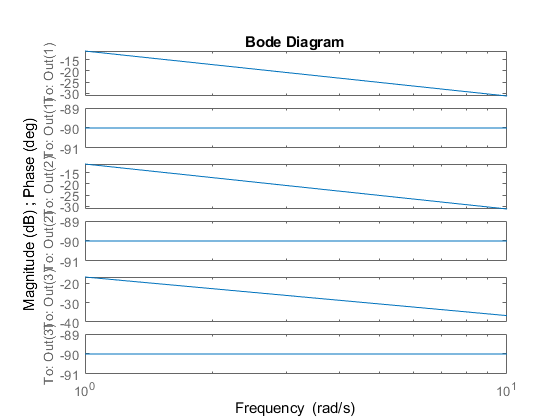


figure
hold on
bode(Y_rp)

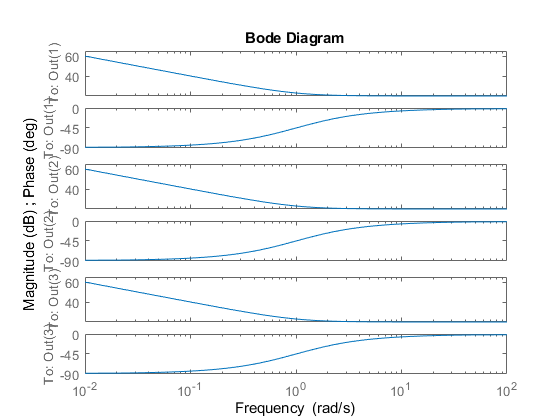

bode(Y_vp)

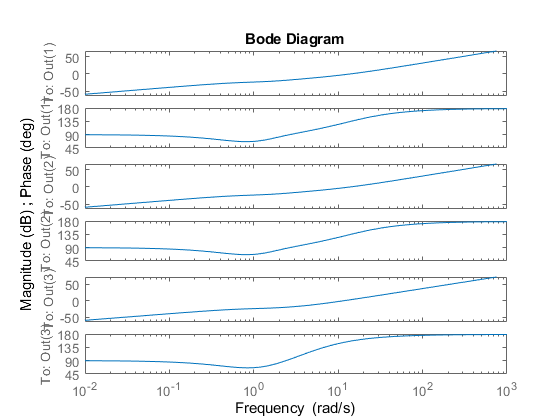

bode(Y_ap)




% to define system transfer function:
% x1 = S_f*F_ext
% x2 = Y_v*x1
% x3 = x2/s - S_p/s*v
% x4 = C_fb_pos*x3
% x5 = inv(J)*H_zoh*x4 - J*v
% x6 = C_fb_vel*x5
% x7 = inv(J')*x6
% v = Y_r*x7
% 
% Y_a = (v/F_ext)
